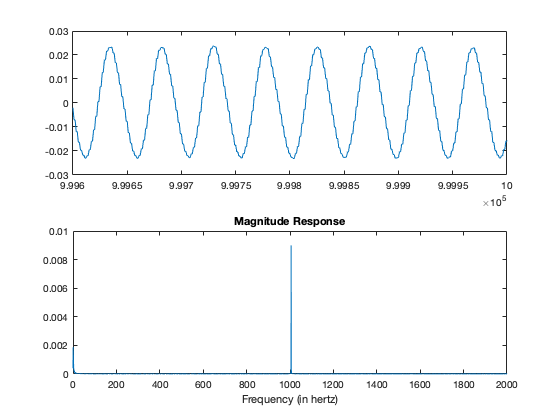

[x, fs] = audioread("Sin_Test.wav");

subplot(2,1,1);
plot(x)
xlim([(1e6)-400 1e6]);
X = fftshift(fft(x));
N = length(x);
%%Frequency specifications:
dF = fs/N;                      
f = -fs/2:dF:fs/2-dF;
%%Plot the spectrum:
subplot(2,1,2)
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
title('Magnitude Response');
xlim([0 2000]);